# Analyzing scRNASeq metabolic model profiles

**Author:** Scott Campit

## Summary

This script analyzes the metabolic fluxes and growth rates from scCOBRA.

## 1. RECON1

### A. Load data

We'll load the latest data, which was simulated using MAGIC imputed scRNA-Seq data. Each cell is stored as an individual .mat file. We'll load up the fluxes and knockout growth rates as a matrix.

% Dell
datapath = dir(fullfile("D:/Analysis/EMT/recon1", "*.mat"));
load D:/Analysis/EMT/scRNASeq_recon1_diffexp.mat

Now let's instantiate several data objects we'll use to store the data.

% Create structure to save data into
flux = zeros(3744, length(datapath));
geneko = zeros(1473, length(datapath));
rxnko = zeros(3744, length(datapath));
id = string();

Finally, let's load up everything.

for i = 1:size(datapath, 1)
    load(strcat(datapath(i).folder, '\', datapath(i).name));
    flux(:, i) = cobra_cell.flux;
    geneko(:, i) = cobra_cell.geneko';
    rxnko(:, i) = cobra_cell.rxnko;
    id(i) = cobra_cell.id;
end

Get reaction and gene IDs

rxn_ids = [model.rxns, model.rxnNames, model.subSystems];
rxnko_ids = [model.rxns, model.rxnNames, model.subSystems];

% Need to map back to gene symbols later - not correct in RECON1 model.
gene_ids = unique(model.geneEntrezID);

### B. Save the data for UMAP embedding

Let's save the matrices now for data visualization.

filename = "D:/Analysis/EMT/recon1_cobra_results.xlsx";

#### i. Reaction fluxes

% Create column names
rxn_colnames = ["ID", "Name", "Subsystem", string(time_course)];

% Create matrix
tmpflx = [rxn_colnames; ...
          string(rxn_ids), string(flux)];

% Write to file
writematrix(tmpflx, filename, 'Sheet', 'Flux')

#### ii. Reaction knockout growth rates

% Create column names
rxnko_colnames = ["ID", "Name", "Subsystem", string(time_course)];

% Create matrix
tmprxnko = [rxn_colnames; ...
            string(rxn_ids), string(rxnko)];

% Write to file
writematrix(tmprxnko, filename, 'Sheet', 'RxnKO');

#### iii. Gene knockout growth rates

% Create column names
gene_colnames = ["Entrez", string(time_course)];

% Create matrix
tmpgeneko = [gene_colnames; ...
             gene_ids, string(geneko)];

% Write to file
writematrix(tmpgeneko, filename, 'Sheet', 'GeneKO');

### C. Construct identifiers by day 

We need to create identifiers by time. 

% Separate based on day
tmp_id = string(length(time_course));
for i = 1:length(time_course)
    try
        tmp = split(string(time_course{i}), ".");
        tmp_id(i) = tmp(1);
    catch ME
        tmp_id(i) = string(time_course{i});
    end
        
end

Also, we'll create indices to partition the data by time point. This loses information about the cells but we'll assume that mesenchymal cells are more prevalent in the later time points while epithelial cells are in the earlier time points.

% Indicies based on timepoints
idx0d = tmp_id == "0d";
idx8h = tmp_id == "8h";
idx1d = tmp_id == "1d";
idx3d = tmp_id == "3d";
idx7d = tmp_id == "7d";

Now let's also create a barplot of the distribution of cells.

figure();
b1 = bar(categorical({'0 hours'}), sum(idx0d));
hold on;
b2 = bar(categorical({'8 hours'}), sum(idx8h));
hold on;
b3 = bar(categorical({'24 hours'}), sum(idx1d));
hold on;
b4 = bar(categorical({'72 hours'}), sum(idx3d));
hold on;
b5 = bar(categorical({'168 hours'}), sum(idx7d));
hold on;

set(b1, 'facecolor', "#022B3A");
set(b2, 'facecolor', "#1F7A8C");
set(b3, 'facecolor', "#BFDBF7");
set(b4, 'facecolor', "#E1E5F2");
set(b5, 'facecolor', "#FFFFFF");

ttl = title("Distribution of single-cells in Cook & Vanderhyden dataset");
ttl.Units = 'Normalize'; 
ttl.Position(1) = 0; 
ttl.HorizontalAlignment = 'left';  

xlabel("Time-course");
ylabel("Number of cells");
ylim([0, 200])
set(gca, 'FontName', 'Arial')

### D. Separate metabolic fluxes by day

First, remove identifiers and return to numerical

tmpflx = str2double(tmpflx(2:end, 4:end));

Now let's separate flux distributions by time point.

flux0d  = tmpflx(:, idx0d);
flux8h  = tmpflx(:, idx8h);
flux1d  = tmpflx(:, idx1d);
flux3d  = tmpflx(:, idx3d);
flux7d  = tmpflx(:, idx7d);

Now let's plot histograms

figure;
h1 = histogram(flux0d, 100);
hold on;
h2 = histogram(flux8h, 100);
hold on;
h3 = histogram(flux1d, 100);
hold on;
h4 = histogram(flux3d, 100);
hold on;
h5 = histogram(flux7d, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");
set(h5, 'facecolor', "#FFFFFF");

legend("0 hours", ...
       "8 hours", ...
       "24 hours", ...
       "72 hours", ...
       "168 hours");
set(gca, 'YScale', 'log')
title("RECON1 metabolic flux distributions on Cook & Vanderhyden data");
xlabel("Predicted metabolic flux for 644 single-cells (mmol/gDW*hr)");
ylabel("Number of reactions");

### E. Metabolic flux fold change comparing day t over day 0

#### i. Get fold change across different time points

I added a value of 1 to not run into infinite values.

fc0008  = (abs(flux8h)+1)  ./ mean(abs(flux0d)+1, 2);
fc0024  = (abs(flux1d)+1)  ./ mean(abs(flux0d)+1, 2);
fc0072  = (abs(flux3d)+1)  ./ mean(abs(flux0d)+1, 2);
fc00168 = (abs(flux7d)+1)  ./ mean(abs(flux0d)+1, 2);

#### ii. Create row index with fold change

fc0008_label  = repmat("Hour 08  / Hour 00", size(fc0008, 1), 1);
fc0024_label  = repmat("Hour 24  / Hour 08", size(fc0024, 1), 1);
fc0072_label  = repmat("Hour 72  / Hour 24", size(fc0072, 1), 1);
fc00168_label = repmat("Hour 168 / Hour 72", size(fc00168, 1), 1);

all_labels = [fc0008_label; fc0024_label; fc0072_label; fc00168_label];

#### iii. Concatenate vertically

df = [fc0008, fc0024, fc0072, fc00168];

#### iv. Remove reactions that have no fold change in any reaction 

keep_idx   = all(df-1, 2);
df         = df(keep_idx, :);
rxn_ids    = rxn_ids(keep_idx, :);

#### v. Let's also apply the log2 operator on the data

log2df = log2(df);
df08  = log2df(:, 1:sum(idx8h));
df24  = log2df(:, (sum(idx8h)+1):(sum(idx1d)+sum(idx8h)));
df72  = log2df(:, (sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168 = log2df(:, (sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h));

#### vi. Let's plot a histogram of the data distribution

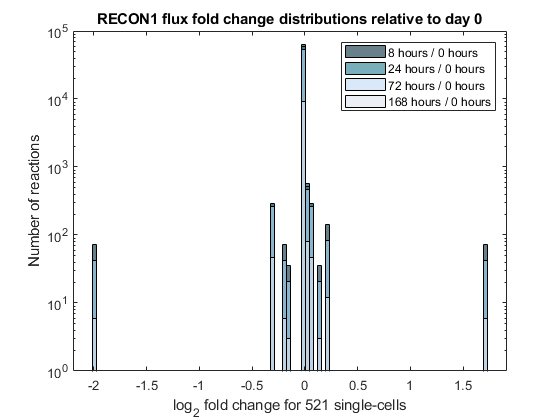

figure;
h1 = histogram(df08, 100);
hold on;
h2 = histogram(df24, 100);
hold on;
h3 = histogram(df72, 100);
hold on;
h4 = histogram(df168, 100);

set(h1, 'facecolor', "#022B3A");
set(h2, 'facecolor', "#1F7A8C");
set(h3, 'facecolor', "#BFDBF7");
set(h4, 'facecolor', "#E1E5F2");

legend("8 hours / 0 hours", ...
       "24 hours / 0 hours", ...
       "72 hours / 0 hours", ...
       "168 hours / 0 hours");
set(gca, 'YScale', 'log')
title("RECON1 flux fold change distributions relative to day 0");
xlabel("log_{2} fold change for 521 single-cells");
ylabel("Number of reactions");

#### vii. Compute average flux and standard deviation for single cells

**Average metabolic fluxes**

Create an average matrix for each time point

df08  = df(1:sum(idx8h), :);
df24  = df((sum(idx8h)+1):(sum(idx1d)+sum(idx8h)), :);
df72  = df((sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168 = df((sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h), :);

First, let's compute the average metabolic flux fold changes.

avg_df08 = mean(df08, 1);
avg_df24 = mean(df24, 1);
avg_df72 = mean(df72, 1);
avg_df168 = mean(df168, 1);

We'll make a single matrix and take the sume of averages across all time points.

% Construct a single matrix of the average metabolic flux fold changes
avg_df = [avg_df08; avg_df24; avg_df72; avg_df168];

% Get the sum of averages across all time points
avg_overall = sum(avg_df, 1);

Let's plot a histogram of the data distribution.

histogram(avg_overall, 100);
xlabel("Average log_{2}(Fold Change)");
ylabel("Number of reactions");
title("Metabolic flux fold-change distribution across all cells")
set(gca, 'YScale', 'log');

**Standard deviation of metabolic fluxes**

% Compute variance of metabolic flux fold changes
var_df08  = var(df08, 1);
var_df24  = var(df24, 1);
var_df72  = var(df72, 1);
var_df168 = var(df168, 1);

We'll make a single matrix and take the sum of variances across all time points.

% Construct a single matrix of the variances
var_df = [var_df08; var_df24; var_df72; var_df168];

% Get the sum of variance across all time points
var_overall = sum(var_df, 1);

**Sort the reactions by overall averages**

% Sort by descending
[~, idx] = sort(avg_overall, 'descend');
avg_ids = string(id);

% Apply descend to matrix
final_df = avg_ids;

**We need to make a string out of the data.**

tmp = [avg_df08',  var_df08', ...
       avg_df24',  var_df24', ...
       avg_df72',  var_df72', ...
       avg_df168', var_df168, ...
       avg_overall', var_overall'];
tmp = string(tmp);

**Now concatenate all of the data**

final_df = [final_df, tmp];
final_df = final_df(idx, :);

**Filter by the variance**

I chose an arbitrary threshold of 1E-5.

idx2     = double(final_df(:, 11)) > 1E-5;
final_df = final_df(idx2, :);

**Map back the reaction formula to the reactions**

rxn = printRxnFormula(model, 'rxnAbbrList', cellstr(final_df(:, 1)));

**Create the final matrix**

final_df = [string(rxn), final_df];
final_df = ["Formula", "ID", "Name", "Subsystem", ...
            "Mean Hour 008", "Var Hour 008", ...
            "Mean Hour 024", "Var Hour 024", ...
            "Mean Hour 072", "Var Hour 072", ...
            "Mean Hour 168", "Var Hour 168", ...
            "Mean Overall",  "Var Overall"; ...
            final_df];

**Write final matrix to file.**

% Write to file
writematrix(tmpgeneko, filename, 'Sheet', 'dt/d0 flux');

### F. Fold change comparing day t over day t-1

#### i. Get fold change across different time points

Now get the fold change across time transitions.

fc0008  = (abs(flux8h)+1)  ./ mean(abs(flux0d)+1);
fc0824  = (abs(flux1d)+1)  ./ mean(abs(flux8h)+1);
fc2472  = (abs(flux3d)+1)  ./ mean(abs(flux1d)+1);
fc72168 = (abs(flux7d)+1)  ./ mean(abs(flux3d)+1);

#### ii. Create row index with fold change

fc0008_label  = repmat("Hour 08  / Hour 00", size(fc0008, 1), 1);
fc0824_label  = repmat("Hour 24  / Hour 08", size(fc0824, 1), 1);
fc2472_label  = repmat("Hour 72  / Hour 24", size(fc2472, 1), 1);
fc72168_label = repmat("Hour 168 / Hour 72", size(fc72168, 1), 1);

all_labels = [fc0008_label; fc0824_label; fc2472_label; fc72168_label];

#### iii. Concatenate vertically

df = [fc0008; fc0824; fc2472; fc72168];

#### iv. Remove reactions that have no fold change in any reaction 

keep_idx   = all(df-1, 1);
df         = df(:, keep_idx);
id         = id(keep_idx, :);
all_labels = all_labels(keep_idx);

#### v. Let's also apply the log2 operator on the data

log2df = log2(df);

#### vi. Let's plot a histogram of the data distribution

histogram(log2df, 100);
xlabel("Flux log_{2}(fold change)");
ylabel("Number of reactions (log-scale)");
title("RECON1 metabolic flux fold-change distribution across all cells")
set(gca, 'YScale', 'log');

#### vii. Compute average flux and standard deviation for single cells

**Average metabolic fluxes**

Create an average matrix for each time point

df08  = df(1:sum(idx8h), :);
df24  = df((sum(idx8h)+1):(sum(idx1d)+sum(idx8h)), :);
df72  = df((sum(idx1d)+sum(idx8h)+1):sum(idx3d)+sum(idx1d)+sum(idx8h), :);
df168 = df((sum(idx3d)+sum(idx1d)+sum(idx8h)+1):sum(idx7d)+sum(idx3d)+sum(idx1d)+sum(idx8h), :);

First, let's compute the average metabolic flux fold changes.

avg_df08 = mean(df08, 1);
avg_df24 = mean(df24, 1);
avg_df72 = mean(df72, 1);
avg_df168 = mean(df168, 1);

We'll make a single matrix and take the sume of averages across all time points.

% Construct a single matrix of the average metabolic flux fold changes
avg_df = [avg_df08; avg_df24; avg_df72; avg_df168];

% Get the sum of averages across all time points
avg_overall = sum(avg_df, 1);

Let's plot a histogram of the data distribution.

histogram(avg_overall, 100);
xlabel("Average log_{2}(Fold Change)");
ylabel("Number of reactions");
title("Metabolic flux fold-change distribution across all cells")
set(gca, 'YScale', 'log');

**Standard deviation of metabolic fluxes**

% Compute variance of metabolic flux fold changes
var_df08  = var(df08, 1);
var_df24  = var(df24, 1);
var_df72  = var(df72, 1);
var_df168 = var(df168, 1);

We'll make a single matrix and take the sum of variances across all time points.

% Construct a single matrix of the variances
var_df = [var_df08; var_df24; var_df72; var_df168];

% Get the sum of variance across all time points
var_overall = sum(var_df, 1);

**Sort the reactions by overall averages**

% Sort by descending
[~, idx] = sort(avg_overall, 'descend');
avg_ids = string(id);

% Apply descend to matrix
final_df = avg_ids;

**We need to make a string out of the data.**

tmp = [avg_df08',  var_df08', ...
       avg_df24',  var_df24', ...
       avg_df72',  var_df72', ...
       avg_df168', var_df168, ...
       avg_overall', var_overall'];
tmp = string(tmp);

**Now concatenate all of the data**

final_df = [final_df, tmp];
final_df = final_df(idx, :);

**Filter by the variance**

I chose an arbitrary threshold of 1E-5.

idx2     = double(final_df(:, 11)) > 1E-5;
final_df = final_df(idx2, :);

**Map back the reaction formula to the reactions**

rxn = printRxnFormula(model, 'rxnAbbrList', cellstr(final_df(:, 1)));

**Create the final matrix**

final_df = [string(rxn), final_df];
final_df = ["Formula", "ID", "Name", "Subsystem", ...
            "Mean Hour 008", "Var Hour 008", ...
            "Mean Hour 024", "Var Hour 024", ...
            "Mean Hour 072", "Var Hour 072", ...
            "Mean Hour 168", "Var Hour 168", ...
            "Mean Overall",  "Var Overall"; ...
            final_df];

**Write final matrix to file.**

% Write to file
writematrix(tmpgeneko, filename, 'Sheet', 'dt/dt-1 flux');

### G. Reaction knockouts comparing day t over day 0

### H. Reaction knockouts comparing day t over day t-1

### F. Separate gene knockouts by day

Remove all reactions that have no differentially sensitive reactions.

% Reactions that are all zeros across all cells
rm_rxns = all(diffsense>=0.99, 2);

% Get IDs and delete unnecessary ones
ids = [recon1.rxns, recon1.rxnNames, recon1.subSystems];
ids(rm_rxns, :) = [];

% Remove reactions in diffsense
data = diffsense;
data(rm_rxns, :) = [];

rm_rxns = all(isnan(data), 2);
ids(rm_rxns, :) = [];
data(rm_rxns, :) = [];

Remove identifiers corresponding to reactions with all 0 flux values.

rm_rxns = all(scRxnFx==0, 2);
scRxnFx(rm_rxns, :) = [];

% Get IDs and delete unnecessary ones
ids = [recon1.rxns, recon1.rxnNames, recon1.subSystems];
ids(rm_rxns, :) = [];

scRxnFx = scRxnFx(:, idx);

[sorted, idx] = sort(sub_timepoints);
sub_timepoints = sub_timepoints(idx);
data = data(:, idx);

y = tsne(data');
gscatter(y(:, 1), y(:, 2), sorted)

avg_effect = mean(abs(data), 2)
all_data = [avg_effect, data];

[all_data, idx] = sortrows(all_data, 1, 'descend');
ids = ids(idx, :);
data = data(idx, :);

redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);
heatmap(data(1:100, 578:1365), ...
    'Colormap', redbluecmap)

clustergram(data, ...
    'Colormap', redbluecmap)

hr0 = mean(data(:, sorted == '0d'), 2);
hr8 = mean(data(:, sorted == '8h'), 2);
day1 = mean(data(:, sorted == '1d'), 2);
day3 = mean(data(:, sorted == '3d'), 2);
day7 = mean(data(:, sorted == '7d'), 2);

median_data = [hr0, hr8, day1, day3, day7];